# Project 2

# Jenna Varnell, Andrea Stancescu, Omry Brewster

We start with loading the joke data which contains 4 items:

1) JTrain, 63 by 42 matrix with ratings 

2) jokes, an array of length 42 labeling jokes

3) jokeTexts, array of length 42 of the jokes written out

4) JTest, 36 by 20 matrix of the first 20 jokes

First we will find the jokes with the highest and lowest ratings.We do this by finding the mean of each column in JTrain and finding the maximum and minimum. 

% part a
load jokesSp22.mat
f=mean(JTrain);
[m1,n1]=max(f);
high=jokeTexts{n1};
[m2,n2]=min(f);
low=jokeTexts{n2};
fprintf('The jokes with the highest ranking was: \n%s\n',high)

The jokes with the highest ranking was: 
An engineer, a physicist and a mathematician are sleeping in a room. There is a fire in the room. The engineer wakes up, sees the fire, picks up the bucket of water and douses the fire and goes back to sleep.   Again there is fire in the room. This time, the physicist wakes up, notices the bucket, fills it with water, calculates the optimal trajectory and douses the fire in minimum amount of water and goes back to sleep.  Again there is fire. This time the mathematician wakes up.  He looks at the fire, looks at the bucket and the water and exclaims, "A solution exists" and goes back to sleep.


fprintf('The jokes with the lowest rating was: \n%s\n',low)

The jokes with the lowest rating was: 
Two cows are in a field. Suddenly, from behind a bush, a rabbit leaps out and runs away. One cow looks around a bit, eats some grass, and then wanders off. 


Next we will find the person that gave the highest average rating on the jokes. We do this by transposing JTrain when we find the mean as before. We are also finding the joke that this specific person ranked the lowest. We do this by finding the minimum in the row that corresponds with the student we just found. 

% part b
h=mean(JTrain');
[m3,n3]=max(h)

m3 = 8

n3 = 11

[m4,n4]=min(JTrain(11,:))

m4 = 6

n4 = 14

fprintf('The student that gave the highest average rating is student number %.0f\n',n3)

The student that gave the highest average rating is student number 11


fprintf('This student gave this jokes the lowest rating: \n%s\n',jokeTexts{n4})

This student gave this jokes the lowest rating: 
Sherlock Holmes and Dr. Watson go on a camping trip, set up their tent, and fall asleep. Some hours later, Holmes wakes his faithful friend. "Watson, look up at the sky and tell me what you see." Watson replies, "I see millions of stars." "What does that tell you?" Watson ponders for a minute. "Astronomically speaking, it tells me that there are millions of galaxies and potentially billions of planets. Astrologically, it tells me that Saturn is in Leo. Timewise, it appears to be approximately a quarter past three. Meteorologically, it seems we will have a beautiful day tomorrow. What does it tell you?" Holmes is silent for a moment, then speaks. "Watson, you idiot, someone has stolen our tent."


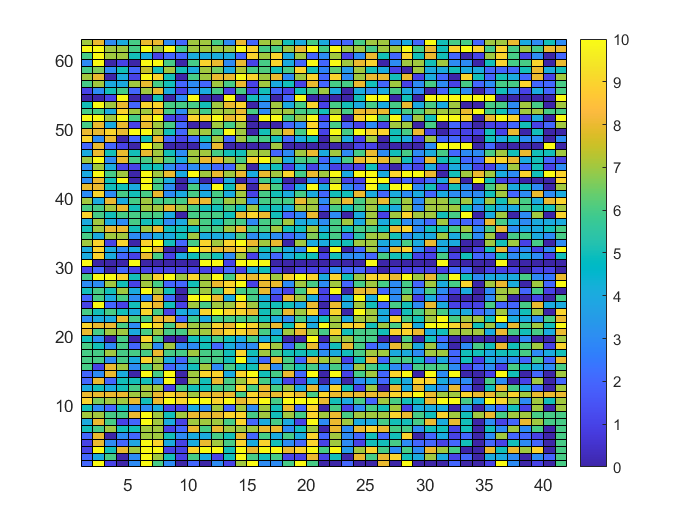

% part c
pcolor(JTrain),colorbar